## Example LiveScript for ECE 485/535 Final Exam:

clear all % clears Matlab's memory (and makes debugging LiveScripts much easier as Matlab's memory persists between LiveScript execution runs.)

load Data_Example.mat %loads the matlab data file for question 1

who % shows the variables that are defined in the matlab data file that are now loaded


Your variables are:

Classes  Data     




% Show the sizes of these loaded variables
size(Classes)

ans =            1        1000


size(Data)

ans =         1000          25



% change Classes from a row variable to a column variable by performing
% vector transpose

Classes = Classes'; % the semicolon tells Matlab not to print the results.
size(Classes) % Classes in now a row variable.

ans =         1000           1



disp(['The unique classes in Classes are:'])

The unique classes in Classes are:


unique(Classes) %find the unique entries in Classes, i.e., the number of classes and their labels

ans =      1
     2


### Perform PCA on the data to reduce it to 2D:

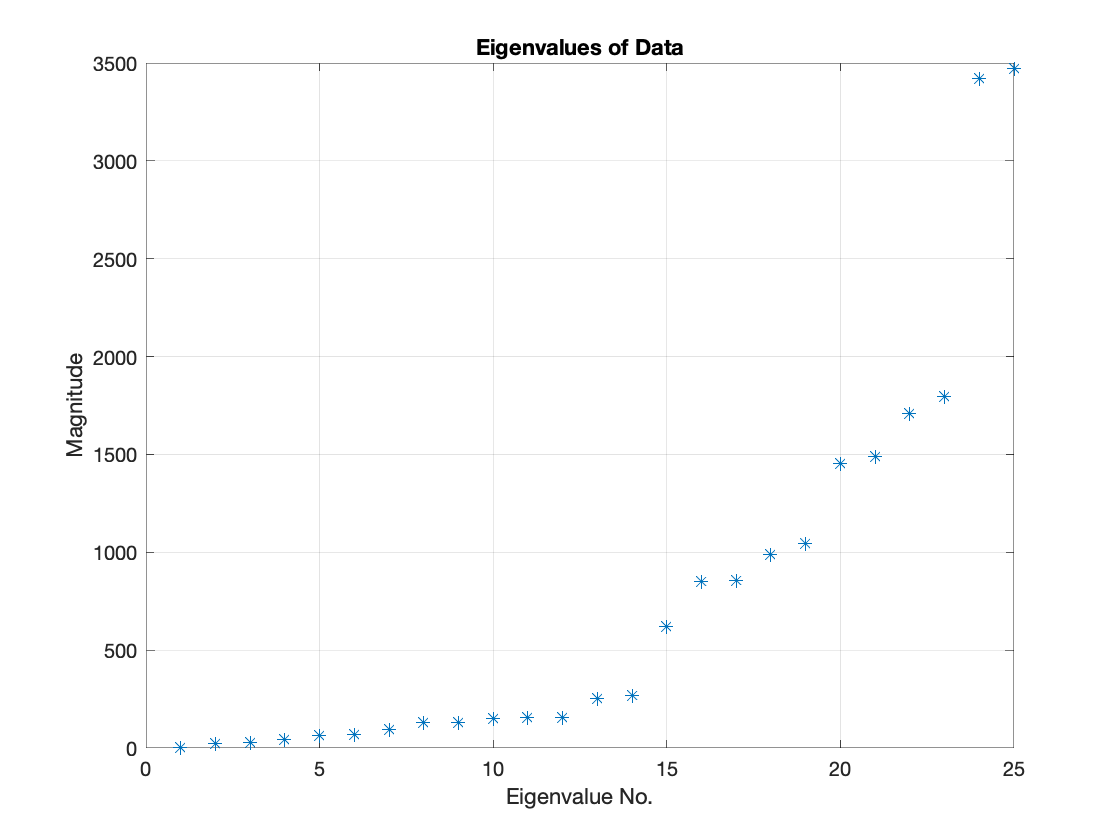

m = mean(Data);

Data = Data - m; % Zero mean data is easier to work with if you are doing tranforms.

C = cov(Data); % compute the data's covariance matric
[e,v] = eig(C); % compute the eigenvalues and vectors of this covariance matric.

v = diag(v); % the eigenvalue are returned as the main diagnonal of a matric to covert this to a vector 

plot(v,'*')
grid on
title('Eigenvalues of Data')
xlabel('Eigenvalue No.')
ylabel('Magnitude')

Note: eig() returns the eigenvalues sorted from smallest to largest.

To do PCA we want to transpose the data along the eigenvectors corresponding to the 2 largest eigenvalues. The eigenvalues are the columns of the variable e.

T = e(:,end-1:end); % select the last two columns of e as transform T (this the same as T = e(:,[24,25])
size(T)  % T is a 25x2 dimensional variable as expected

ans =     25     2


The variable Data is row-wise with each row representing a data pont and each column representing on the the 25 dimensions (We can tell it is row wise as it is a 1000x25 dimensional variable and we know there are 1000 data samples.)

Hence, transforming the data from its orginal 25 dimensions down to the best 2 linear dimensions, i.e, applying PCA, can be done as:

Data_new = Data*T; % Applying PCA (to all data samples in one step)
size(Data_new) % The new data is 1000 samples in 2 dimensions

ans =         1000           2


**Note:** The above highlights that within Matlab PCA can be done in 2 lines:

    c = cov(Data);

    [e,v] = eig(c);

    new_Data = Data*e(:,end-1:end);

In general, to make debugging easier you do not want to make more complex compound statements like "[e,v] = eig(cov(Data));" as this doesn't let you check that cov(Data) has the form that you were expecting, i.e., if the Data has outliers then cov(Data) will look different than if it does not and this will effect the nature of the eigenvectors and eigenvalues.

Now find the data points from Class1 and those from Class2:

i1 = find(Classes == 1); % finds all the indices of Classes that have the value of 1
i2 = find(Classes == 2); % finds all the indices of Classes that have the value of 2

Now plot the transformed data and colour the data from each class seperately

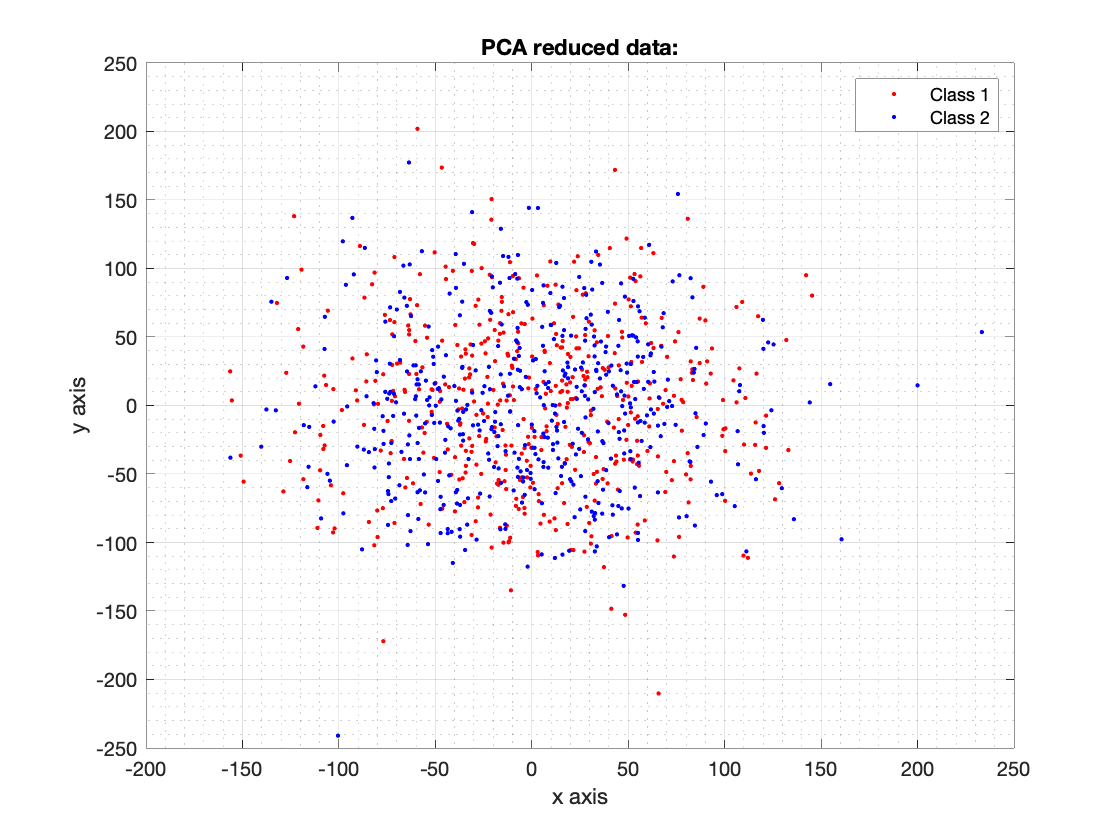

plot(Data_new(i1,1),Data_new(i1,2),'r.') % plot Class 1 data with red dots
hold on % put hold on on the plot to allow more than one plot to be done on the same plot
plot(Data_new(i2,1),Data_new(i2,2),'b.') % plot Class 2 data with blue dots

xlabel('x axis')  % properly label the x-axis, y-axis, and title of the plot
ylabel('y axis')
title('PCA reduced data:')
legend('Class 1', 'Class 2') % put a legend on the plot
grid on 

grid minor %turn on minor grid markings 

**Note: **As expected PCA does a poor job of seperating the classes as it uses no class information to compute its transform

*- END of Example LiveScript -*